% Experiment on the Cascaded watertanks benchmark
%
% References
% ---------
%
% A Tensor Network Kalman filter with an application in recursive MIMO Volterra system identification
% 2016, Kim Batselier, Zhongming Chen, Ngai Wong
% 

clear all
close all
clc

%for reproducibility
rng(1);

load('dataBenchmark')


Preprocessing Data

tic

% Normalize the input and output training data to [0 1]
input = uEst/7;
output = yEst/10-0.1;

% plot(input)
% plot(output)
% 
% histogram(input)
% histogram(output)

% Normalize the input and output test data to [0 1]
tinput = uVal/7 ;
toutput = yVal/10-0.1;

% Choose the lags for the input and output
inlags=[1 2];
outlags=[0 1 2 3 4 8 16];
% outlags=[0 1 2 3 4];

inlags=[1 2 3 4 8 16 32];
outlags=[0 1 2 3 4 8 16 32];

ending = 1024-max(outlags(end),inlags(end))-1;

% generate features using input lags
for l = 1:length(inlags)
u(:,l) = input(end-inlags(l)-ending:end-inlags(l));
uv(:,l) = tinput(end-inlags(l)-ending:end-inlags(l));
end
% generate features using output lags
for l = 1:length(outlags)
y(:,l) = output(end-outlags(l)-ending:end-outlags(l));
yv(:,l) = toutput(end-outlags(l)-ending:end-outlags(l));
end



Split test and training set

% Features are lagged inputs and outputs
featurez = [y(:,end:-1:2)  u];
% Target is output with zero lag
zeta = y(:,1);

tfeaturez = [yv(:,end:-1:2)  uv];
yt = yv(:,1);


Construct B-spline basis vectors


[N, d]=size(featurez); % Number of samples and features

n = 3;                  %Degree B-spline
m = 1;                  %Number of knot intervals
In = n+m;               %Number of B-splines



Initialize tensor train

% Choose TT-ranks
maxrank = 8;

r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank));



% 
% LAM = [10 1 10^-1 10^-2 10^-3 10^-4 10^-5]
% nselect = logspace(log10(10*dof/N),0,10);
% 
% LAM = logspace(log10(0.3360*10^-3),log10(0.0183*10^-3),20);

LAM = logspace(-4,-7,10);

difforder=2;
MAXITR = 2*d;

tic
for period = 1:numel(LAM)

    lambda = LAM(period);
    
for trial = 1:3
% selc= setdiff(1:length(featurez),(trial-1)*252+1:trial*252);
% selc = randperm(length(featurez),900);

tselc = (1:200)+(trial-1)*200;
selc = setdiff(1:length(featurez),tselc);

fold = featurez(selc,:);
tfold = featurez(tselc,:);

Nf= size(fold, 1);

unf = basisvectors(fold,n,m);

for initial = 1:1
[TNf,Vmf,Vpf] = initTT(unf,r,d);

[TN,~,~,~,~] = optimTT(TNf,Vmf,Vpf,unf,zeta(selc),MAXITR,[],lambda,difforder);
% [simoutput] = simnarx(TN,tinput,toutput,inlags,outlags,n,m);
% RMSE_S(period,trial,initial) = sqrt(immse(10*toutput,10*simoutput));

yhat = evalspline(TN,tfold,n,m);
RMSE_P(period,trial,initial) = sqrt(immse(10*yhat,10*zeta(tselc)));
end
end
% figure
% hold on
% plot(10*toutput+1,'linewidth',2)
% plot(10*simoutput+1,'linewidth',2)
% hold off

% figure
% hold on
% plot(10*yt+1,'linewidth',2)
% plot(10*yhat+1,'linewidth',2)
%  hold off

end
toc

Elapsed time is 3.816885 seconds.


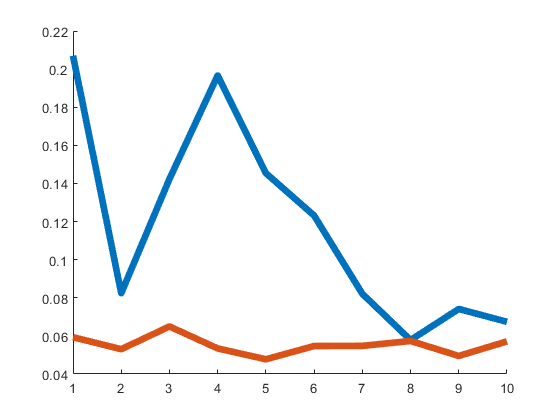


figure
hold on
% plot(RMSE_P)
% plot(RMSE_S)
plot(squeeze(mean(RMSE_P,2)),"LineWidth",5)
plot(squeeze(median(RMSE_P,2)),"LineWidth",5)
% plot(mean(RMSE_S,2),"LineWidth",5)
hold off


% scatter(mean(RMSE_P,2),mean(RMSE_S,2))
% scatter(median(RMSE_P,2),median(RMSE_S,2))

% [~,hyp] = min(median(median(RMSE_P,2),3));
[~,hyp] = min(mean(mean(RMSE_P,2),3));
lambda = LAM(hyp)

lambda = 4.6416e-07



% Construct the basis vectors from the features
un = basisvectors(featurez,n,m);

% Initialize Tensor Train and Vp and Vm
[TN,Vm,Vp] = initTT(un,r,d);


Optimize TT cores

% rez = [];

% lambda=1*10^-5;

difforder=1;
MAXITR = 2*d;

% nselect = floor(logspace(log10(dof/N),0,MAXITR)*0.5*N);

tic
[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,[],lambda,difforder);
toc

Elapsed time is 3.815617 seconds.


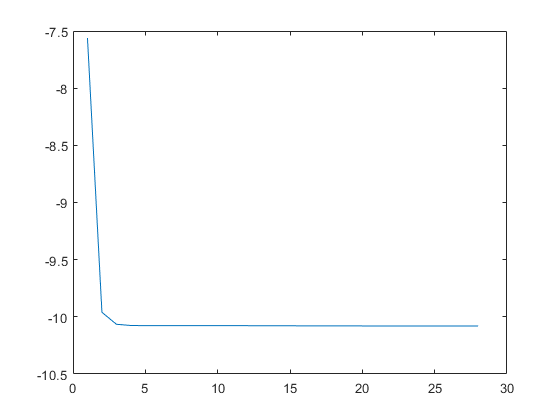

plot(log(res1))

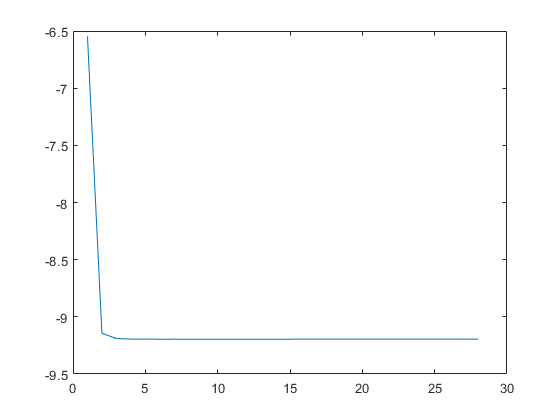

plot(log(res2))

Evaluate Train data

% trainerror = res1(end)

trainerror = 4.1914e-05

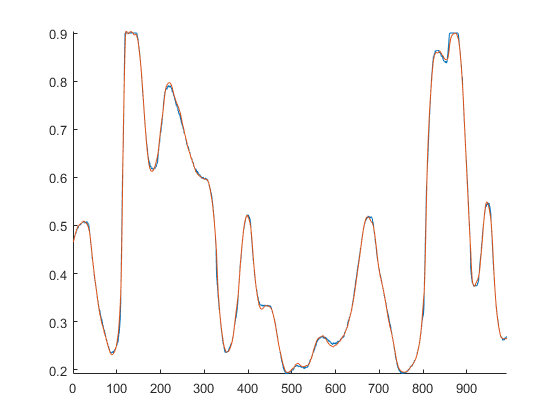

% 
% yhattrain  = evalspline(TN,featurez,n,m);
% 
% figure;
% hold on
% plot(zeta)
% plot(yhattrain)
% hold off
% axis([0 inf -inf inf]);

% 
% erboiz = (yhattrain-zeta);
% VAF = 1-var(erboiz)/var(zeta)

VAF = 0.9991

% MSE = immse(yhattrain,zeta)

MSE = 4.1914e-05

Evaluate Test data


yhat = evalspline(TN,tfeaturez,n,m);
erboi = (yhat-yt);
% histogram((erboi)');
VAF = 1-var(erboi)/var(yt)

VAF = 0.9973

RMSE_Pt = sqrt(immse(10*yhat,10*yt))

RMSE_Pt = 0.1104

 Visualize errors

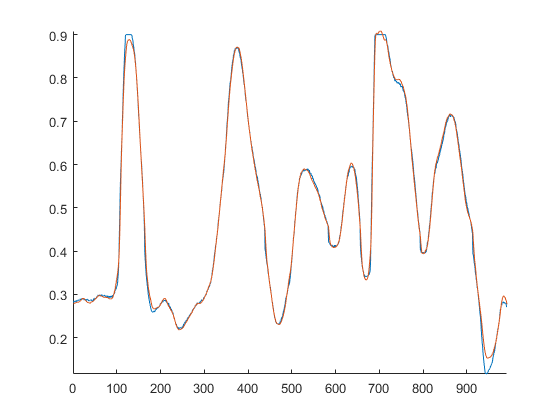

figure
hold on
plot(yt)
plot(yhat)
hold off
axis([0 inf -inf inf])

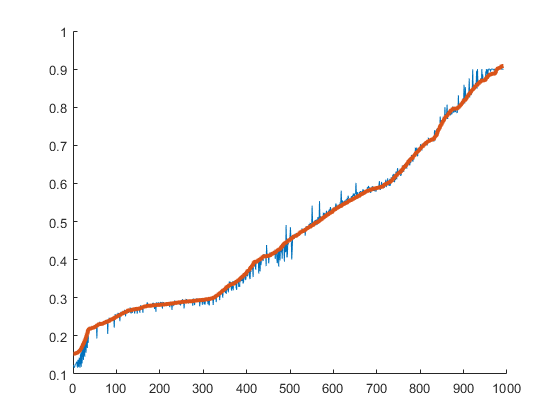


[sortout,Iss]=sort(yhat);
figure
hold on
plot(yt(Iss))
plot(sortout,'Linewidth',3)
hold off


[simoutput] = simnarx(TN,tinput,toutput,inlags,outlags,n,m);

fig = figure

fig =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 22
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


hold on
plot(10*toutput+1,'linewidth',2)
plot(10*simoutput+1,'linewidth',2)
hold off
beginz = max(outlags(end),inlags(end)) +1;
RMSE_St = sqrt(immse(10*toutput(beginz:end),10*simoutput(beginz:end)))

RMSE_St = 0.3128

toc

Elapsed time is 4.797455 seconds.


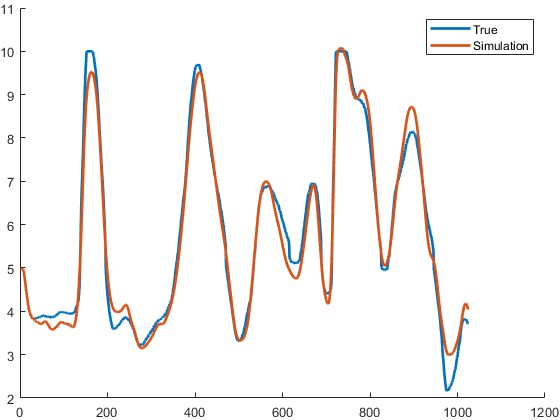

legend('True', 'Simulation')


T = get(gca,'tightinset');
set(gca,'position',[T(1) T(2) 1-T(1)-T(3) 1-T(2)-T(4)]);
print(fig,'MySavedFile','-depsc')

% surf(RMSE)
% xlabel('lambda * 10^-2')
% ylabel('RMSE')
% 
% zlabel('RMSE')
% plot(RMSE)
% xlabel('lambda * 10^-2')
% ylabel('RMSE')
% 
% bar(1:5,RMSE(6:10))

siminput = tinput;
simoutput = zeros(32,1)

simoutput =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


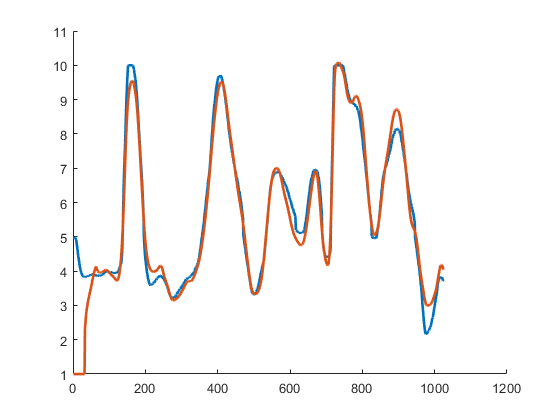

numz = numel(outlags);
beginz = max(outlags(end),inlags(end))+1;
for j = beginz:1024
simfeaturez = [simoutput(j-outlags(end:-1:2))' siminput(j-inlags(1:end))'];
simfeaturez(simfeaturez<0)=0;
simfeaturez(simfeaturez>1)=1;
simoutput(j) = evalspline(TN,simfeaturez,n,m);
end

figure
hold on
plot(10*toutput+1,'linewidth',2)
plot(10*simoutput+1,'linewidth',2)
hold off


RMSE = sqrt(immse(10*toutput(1:end),10*simoutput(1:end)))

RMSE = 0.6834

toc

Elapsed time is 144.705340 seconds.


Show storage compression ratio


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %compression ratio

Compression: 1.061e-05
